# 基本的な確率分布の描画と性質

使用 toolbox

    Statistics and Machine Learning Toolbox 

ここでは、makedist を用いて統一した表記を紹介する。

## 1.  一様分布

### 分布オブジェクトの生成

例として、下限 $-3$、上限 $+5$ の連続一様分布オブジェクトを作成する。

xl = -3;
xu = 5;
pd1 = makedist("Uniform", lower=xl, upper=xu);

### 分布の描画

$-10$から $+10$ の範囲で確率密度関数と累積分布を描く

x = -10:0.01:10;
    plot(x, pdf(pd1, x), 'b-', LineWidth=1.5, DisplayName="uniform")
hold on
    pd1_m = mean(pd1) %平均値の計算
    pd1_s = std(pd1) %標準偏差の計算
    xline(pd1_m, 'r--', LineWidth=1, DisplayName="$x = \mu$")
    xline(pd1_m + pd1_s, 'k--', LineWidth=1, DisplayName="$x = \mu + \sigma$")
    xline(pd1_m - pd1_s, 'k--', LineWidth=1, DisplayName="$x = \mu + \sigma$")
hold off
title('pdf of uniform distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$p(x)$", Interpreter="latex", FontSize=13)
legend(Interpreter="latex", Location="southwest")

plot(x, cdf(pd1, x), 'b-', LineWidth=1.5)
title('cdf of uniform distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$Q(x)$", Interpreter="latex", FontSize=13)


### 乱数の生成

一様分布に従う乱数を10000個生成し、ヒストグラムを描画する

rd1 = random(pd1,[1 10000]);
histogram(rd1, 20)
title('histogram of uniform random numbers', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("frequency", Interpreter="latex", FontSize=13)


## 2．指数分布

### 分布オブジェクトの生成

例として、平均 1.7 の指数分布オブジェクトを作成する。

mu = 1.7;
pd2 = makedist("Exponential", mu);

### 分布の描画

$0$から $+10$ の範囲で確率密度関数と累積分布を描く

x = 0:0.01:10;
plot(x, pdf(pd2, x), 'b-', LineWidth=1.5, DisplayName="$\mu =$"+string(mu))
hold on
    pd2_m = mean(pd2) %平均値の計算
    pd2_s = std(pd2) %標準偏差の計算
    xline(pd2_m, 'r--', LineWidth=1, DisplayName="$x = \mu$")
    xline(pd2_m + pd2_s, 'm--', LineWidth=1, DisplayName="$x = \mu + \sigma$")
    xline(pd2_m - pd2_s, 'c--', LineWidth=1, DisplayName="$x = \mu - \sigma$")
hold off
title('pdf of exponential distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$p(x)$", Interpreter="latex", FontSize=13)
legend(Interpreter="latex")

plot(x, cdf(pd2, x), 'b-', LineWidth=1.5, DisplayName="$\mu =$"+string(mu))
title('cdf of exponential distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$Q(x)$", Interpreter="latex", FontSize=13)
legend(Interpreter="latex", Location="southeast")


### 乱数の生成

乱数を生成し、ヒストグラムを描画する

さらに、指数分布でのフィッティングを行う

rd2 = random(pd2,[1 10000]);
f2 = fitdist(rd2',"exponential");
h2 = histfit(rd2, 30,"exponential");
h22 = h2(2);
set(h22, DisplayName="$\mu =$"+string(f2.mu))
title('histogram of exponential random numbers', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("frequency", Interpreter="latex", FontSize=13)
legend(h22, Interpreter="latex")


## 3．二項分布

### 分布オブジェクトの生成

例として、 $N=100$、 $p=0.35$ の二項分布オブジェクトを作成する。

N3 = 100;
p3 = 0.35;
pd3 = makedist("Binomial", "N", N3, "p", p3);

### 分布の描画

$0$から $+10$ の範囲で確率密度関数と累積分布を描く

x = 0:1:100;
plot(x, pdf(pd3, x), 'bo-', LineWidth=1, DisplayName="$N =$"+string(N3)+", $p =$"+string(p3))
hold on
    pd3_m = mean(pd3);
    pd3_s = std(pd3);
    xline(pd3_m, 'r--', LineWidth=1, DisplayName="$x = \mu$")
    xline(pd3_m + pd3_s, 'm--', LineWidth=1, DisplayName="$x = \mu + \sigma$")
    xline(pd3_m - pd3_s, 'c--', LineWidth=1, DisplayName="$x = \mu + \sigma$")
hold off
title('pdf of binomial distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$p(x)$", Interpreter="latex", FontSize=13)
legend(Interpreter="latex")

plot(x, cdf(pd3, x), 'bo-', LineWidth=1)
title('cdf of binomial distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$Q(x)$", Interpreter="latex", FontSize=13)

### 乱数の生成

乱数を生成し、ヒストグラムを描画する

rd3 = random(pd3,[1 10000]);
f3 = fitdist(rd3',"normal");
h3 = histfit(rd3, 35,"normal");
h32 = h3(2);
set(h32, DisplayName="$\mu =$"+string(f3.mu))
title('histogram of binomial random numbers', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("frequency", Interpreter="latex", FontSize=13)
legend(h32, Interpreter="latex")


## 4．ポアソン分布

### 分布オブジェクトの生成

例として、 $\lambda=10$ のポアソン分布オブジェクトを作成する。

lambda = 10;
pd5 = makedist("Poisson", "lambda", lambda);

### 分布の描画

$0$から $+10$ の範囲で確率密度関数と累積分布を描く

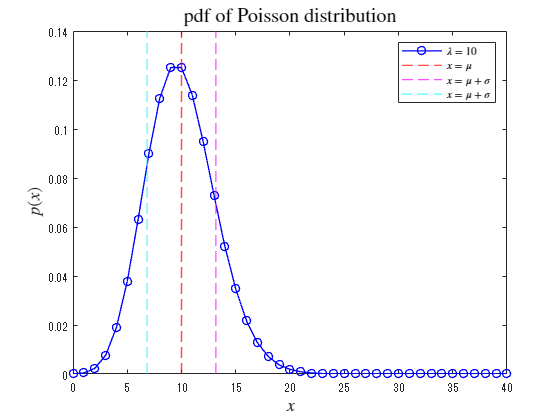

x = 0:1:40;
plot(x, pdf(pd5, x), 'bo-', LineWidth=1, DisplayName="$\lambda =$"+string(lambda))

hold on
    pd5_m = mean(pd5);
    pd5_s = std(pd5);
    xline(pd5_m, 'r--', LineWidth=1, DisplayName="$x = \mu$")
    xline(pd5_m + pd5_s, 'm--', LineWidth=1, DisplayName="$x = \mu + \sigma$")
    xline(pd5_m - pd5_s, 'c--', LineWidth=1, DisplayName="$x = \mu + \sigma$")
hold off
title('pdf of Poisson distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$p(x)$", Interpreter="latex", FontSize=13)
legend(Interpreter="latex")

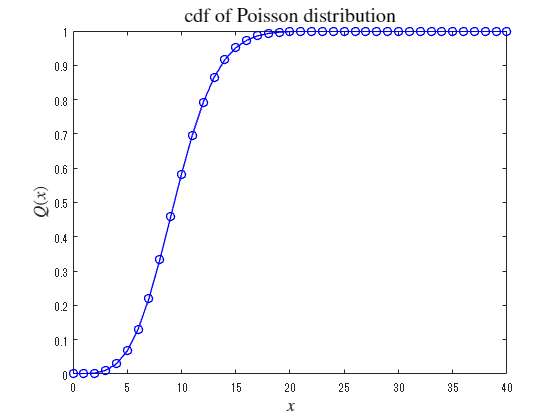


plot(x, cdf(pd5, x), 'bo-', LineWidth=1)
title('cdf of Poisson distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$Q(x)$", Interpreter="latex", FontSize=13)

### 乱数の生成

乱数を生成し、ヒストグラムを描画する

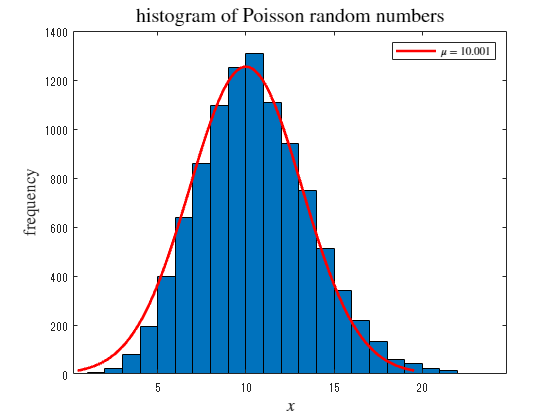

rd5 = random(pd5,[1 10000]);
f5 = fitdist(rd5',"normal");
h5 = histfit(rd5, 23,"normal");
h52 = h5(2);
set(h52, DisplayName="$\mu =$"+string(f5.mu))
title('histogram of Poisson random numbers', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("frequency", Interpreter="latex", FontSize=13)
legend(h52, Interpreter="latex")

## 5．正規分布（ガウス分布）

### 分布オブジェクトの生成

例として、 $\mu=5$、 $\sigma=2.1$ の二項分布オブジェクトを作成する。

mu4 = 5;
sigma4 = 2.1;
pd4 = makedist("normal","mu", mu4, "sigma", sigma4);

### 分布の描画

$0$から $+10$ の範囲で確率密度関数と累積分布を描く

x = -5:0.01:15;
plot(x, pdf(pd4, x), 'b-', LineWidth=1.5, DisplayName="$\mu =$"+string(mu4)+", $\sigma =$"+string(sigma4))
hold on
    pd4_m = mean(pd4)
    pd4_s = std(pd4)
    xline(pd4_m, 'r--', LineWidth=1, DisplayName="$x = \mu$")
    xline(pd4_m + pd4_s, 'm--', LineWidth=1, DisplayName="$x = \mu + \sigma$")
    xline(pd4_m - pd4_s, 'c--', LineWidth=1, DisplayName="$x = \mu + \sigma$")
hold off
title('pdf of normal distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$p(x)$", Interpreter="latex", FontSize=13)
legend(Interpreter="latex")

plot(x, cdf(pd4, x), 'b-', LineWidth=1.5)
title('cdf of normal distribution', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("$Q(x)$", Interpreter="latex", FontSize=13)

### 乱数の生成

乱数を生成し、ヒストグラムを描画する

rd4 = random(pd4,[1 10000])
f4 = fitdist(rd4',"normal");
h4 = histfit(rd4, 30,"normal");
h42 = h4(2);
set(h42, DisplayName="$\mu =$"+string(f4.mu)+", $\sigma =$"+string(f4.std))
title('histogram of normal random numbers', Interpreter='latex', FontSize=15)
xlabel("$x$", Interpreter="latex", FontSize=13)
ylabel("frequency", Interpreter="latex", FontSize=13)
legend(h42, Interpreter="latex")

## 参考文献

- [https://jp.mathworks.com/help/stats/index.html?s_tid=CRUX_lftnav](https://jp.mathworks.com/help/stats/index.html?s_tid=CRUX_lftnav)

- [https://jp.mathworks.com/help/stats/histfit.html](https://jp.mathworks.com/help/stats/histfit.html)

- [https://jp.mathworks.com/help/stats/fitdist.html](https://jp.mathworks.com/help/stats/fitdist.html)